## Měření průtoku vzduchu

## Úkol 1. Proměřování převodních charakteristik

clc
clear 
close all

RGB = orderedcolors("gem");
H = rgb2hex(RGB);


% Referenční hodnoty - plovákový průtokoměr nl/min^(-1)
Q_plov = [22.5, 40, 60, 80, 100, 120, 140, 160, 180, 200, 220];

% Osa x pro trendy
trend_x_axis = 0:0.5:220;

### (a) Škrtící člen (clona) o průměru 12 mm

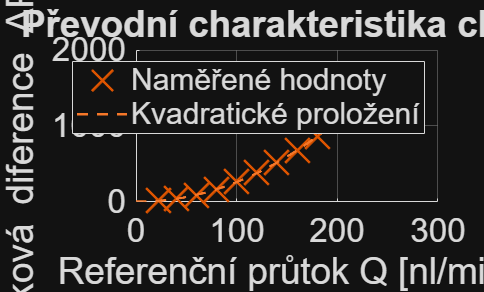

% Proměnné
delta_P_clon = [ 11, 41, 86, 164, 261, 380, 515, 677, 861, 1069, 1300];

% Trend -> Parabola
fit_clona_Q = fit(Q_plov.', delta_P_clon.',"poly2");

% Graf
figure(1)
    hold on
    plot(Q_plov, delta_P_clon, 'x',markersize=21,linewidth=1.5,Color=RGB(2,:));
    plot(fit_clona_Q, '--');
    %set(Q_clona, 'Color', RGB(1,:))
    title("Převodní charakteristika clony")
    legend("Naměřené hodnoty", "Kvadratické proložení")
    xlabel("Referenční průtok Q [nl/min]")
    ylabel("Tlaková diference \DeltaP [Pa]")
    fontsize(scale=1.95)
    grid on;
        hold off;

### (b) Vírový průtokoměr (vortex) EGGS DELTA PULSE FLP15-G2PA

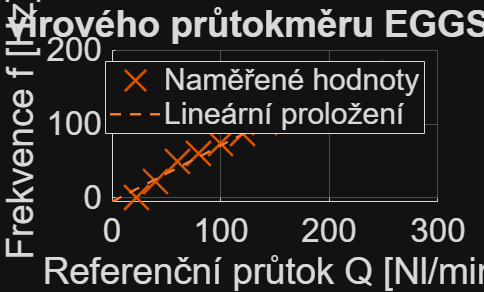

% Proměnné
f_vir = [ 0, 22.82, 49.92, 60.24, 73.70, 87.79, 102.4, 116.6, 131.3, 147.0, 156.2];

% Trend -> Primka
fit_clona_Q_vir = fit(Q_plov.', f_vir.',"poly1");

% Graf
figure(2)
    hold on
    plot(Q_plov, f_vir, 'x',LineWidth=1.5,Color=RGB(2,:),markersize=21);
    plot(fit_clona_Q_vir, "--")
    legend("Naměřené hodnoty", "Lineární proložení")
    xlabel("Referenční průtok Q [Nl/min]")
    ylabel("Frekvence f [Hz]")
    fontsize(scale=1.95)

    title("Převodní charakteristika vírového průtokměru EGGS DELTA PULSE FLP15-G2PA")
    grid on;
        hold off;

### (c) Termoanemometr IST FS5.A

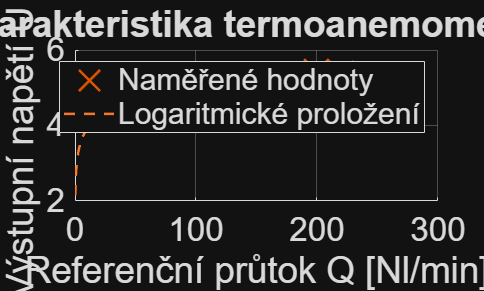

% Proměnné
U_termo = [4.335, 4.555, 4.732, 4.929, 4.995, 5.084, 5.156, 5.217, 5.274, 5.433, 5.372];

% Trend -> Odmocnina
%sqrt_fit = fittype("a*x^b + c");
fit_clona_Q_termo = fit(Q_plov.', U_termo.','log');

% Graf
figure(3)
    hold on
    plot(Q_plov, U_termo, 'x',LineWidth=1.5,Color=RGB(2,:),markersize=21);
    plot(fit_clona_Q_termo, "--");
    title("Převodní charakteristika termoanemometru IST FS5.A")
    legend("Naměřené hodnoty", "Logaritmické proložení")
    xlabel("Referenční průtok Q [Nl/min]")
    ylabel("Výstupní napětí U [V]")
    fontsize(scale=1.95)
    grid on;
        hold off;

### (d) Kalorimetrický průtokoměr HONEYWELL AWM 720P1

% Proměnné
U_kal = [ 2.456, 3.124, 3.632, 3.996, 4.167, 4.323, 4.412, 4.490, 4.550, 4.600, 4.633];

% Trend -> Odmocnina
fit_clona_Q_kal = fit(Q_plov.', U_kal.', 'log');
fit_coef = coeffvalues(fit_clona_Q_kal)

fit_coef =     0.9564   -0.3625


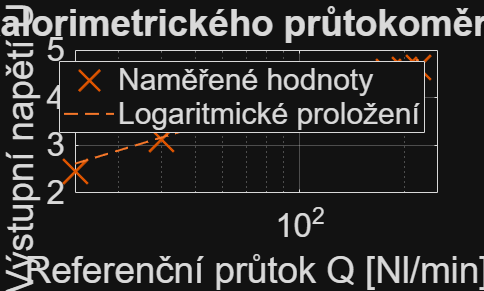


kal_fit = fit_coef(1) * log(Q_plov) + fit_coef(2);
% Graf
figure(4)
    
    semilogx(Q_plov, U_kal, 'x',LineWidth=1.5, Color=RGB(2,:),markersize=21);
    xlim([0 250])
    hold on
    fit_kal = semilogx(Q_plov, kal_fit, "--",LineWidth=1.2);
    legend("Naměřené hodnoty", "Logaritmické proložení")
    xlabel("Referenční průtok Q [Nl/min]")
    ylabel("Výstupní napětí U [V]")
    fontsize(scale=1.95)

    title("Převodní charakteristika kalorimetrického průtokoměru HONEYWELL AWM 720P1")
    grid on;
        hold off;

## Úkol 2. Měření tlakových ztrát

% Referenční hodnoty - plovákový průtokoměr
I_plov = [11.94, 11.99, 12.02, 12.10, 12.22, 12.40, 12.61, 12.87, 13.19, 13.56, 15.01];
P_plov = (I_plov-4)*125

P_plov = 1.0e+03 *

    0.9925    0.9988    1.0025    1.0125    1.0275    1.0500    1.0762    1.1087    1.1487    1.1950    1.3762



% Trend -> Polynom
fit_clona_P_plov = fit(Q_plov.', P_plov.',"poly2");



### (a) Škrtící člen (clona) o průměru 12 mm

% Proměnné
I_clon = [ 3.996, 4.160, 4.463, 4.882, 5.516, 6.227, 7.033, 8.017, 9.096, 10.27, 11.64];
P_clon = (I_clon-4)*125

P_clon =    -0.5000   20.0000   57.8750  110.2500  189.5000  278.3750  379.1250  502.1250  637.0000  783.7500  955.0000



fit_clona_P_clon = fit(Q_plov.', P_clon.',"poly2");
p_clon_coeffs = coeffvalues(fit_clona_P_clon)

p_clon_coeffs =     0.0199    0.0181  -13.0994



p_clon_fit = p_clon_coeffs(1)*Q_plov.^2 + p_clon_coeffs(2)*Q_plov + p_clon_coeffs(3);


### (b) Vírový průtokoměr (vortex) EGGS DELTA PULSE FLP15-G2PA

% Proměnné
I_vir = [ 4.040, 4.323, 4.805, 5.458, 6.361, 7.396, 8.672, 10.04, 11.66, 13.32, 15.38];
P_vir = (I_vir-4)*125

P_vir = 1.0e+03 *

    0.0050    0.0404    0.1006    0.1823    0.2951    0.4245    0.5840    0.7550    0.9575    1.1650    1.4225




fit_clona_P_vir = fit(Q_plov.', P_vir.',"poly2");

p_vir_coeffs = coeffvalues(fit_clona_P_vir)

p_vir_coeffs =     0.0284    0.2782  -17.1086



p_vir_fit = p_vir_coeffs(1)*Q_plov.^2 + p_vir_coeffs(2)*Q_plov + p_vir_coeffs(3);

### (c) Termoanemometr IST FS5.A

% Proměnné
I_term = [ 0, 5, 9, 11, 9, 13, 16, 22, 23, 20, 26];
P_term = (I_term-4)*125

P_term =         -500         125         625         875         625        1125        1500        2250        2375        2000        2750


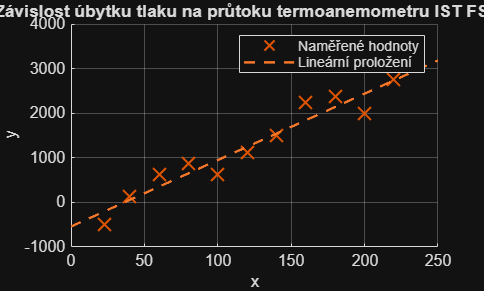


fit_clona_P_term = fit(Q_plov.', P_term.',"poly1");

figure(8)
    hold on
    plot(Q_plov, P_term, 'x',LineWidth=1.2, Color=RGB(2,:),markersize=11);
    plot(fit_clona_P_term, "--");
    title("Závislost úbytku tlaku na průtoku termoanemometru IST FS5.A")
    grid on;
    legend("Naměřené hodnoty", "Lineární proložení");
        hold off;

### (d) Kalorimetrický průtokoměr HONEYWELL AWM 720P1

% Proměnné
I_kal = [4.014, 4.148, 4.353, 4.641, 4.944, 5.356, 5.765, 6.263, 6.764, 7.346, 8.006];
P_kal = (I_kal-4)*125

P_kal =     1.7500   18.5000   44.1250   80.1250  118.0000  169.5000  220.6250  282.8750  345.5000  418.2500  500.7500



fit_clona_P_kal = fit(Q_plov.', P_kal.',"poly2");

p_kal_coeffs = coeffvalues(fit_clona_P_kal)

p_kal_coeffs =     0.0082    0.5410  -15.9244


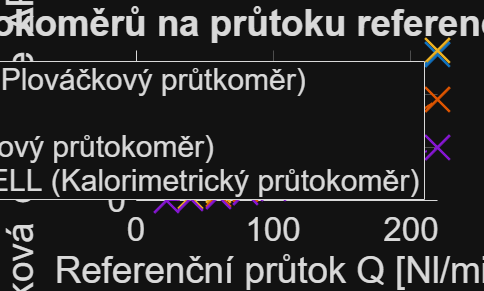


p_kal_fit = p_kal_coeffs(1)*Q_plov.^2 + p_kal_coeffs(2)*Q_plov + p_kal_coeffs(3);

figure(9)
    hold on
    plot(Q_plov, P_plov, "x", MarkerSize=21, Color=RGB(1,:),LineWidth=1.5 );
    plot(Q_plov, P_clon, 'x', MarkerSize=21, Color=RGB(2,:),LineWidth=1.5);
    plot(Q_plov, P_vir, 'x', MarkerSize=21, Color=RGB(3,:),LineWidth=1.5);
    plot(Q_plov, P_kal, 'x', MarkerSize=21, Color=RGB(4,:),LineWidth=1.5);
    fit2 = plot(Q_plov, p_clon_fit, "--",LineWidth=1.2);

    fit3 = plot(Q_plov, p_vir_fit, "--",LineWidth=1.2);

    fit4 = plot(Q_plov, p_kal_fit, "--",LineWidth=1.2);
    plot(Q_plov, P_plov, "--", MarkerSize=17, Color=RGB(1,:),LineWidth=1.2 );
    set(fit2, 'Color', RGB(2,:))
    set(fit3, 'Color', RGB(3,:))
    set(fit4, 'Color', RGB(4,:))
    legend("KROHNE (Plováčkový průtkoměr)", "CLONA", "EGGS (Vírový průtokoměr)", "HONEYWELL (Kalorimetrický průtokoměr)")
    xlabel("Referenční průtok Q [Nl/min]")
    ylabel("Tlaková diference \DeltaP [Pa]")
    fontsize(scale=1.95)
    title("Závislost úbytku tlaku průtokoměrů na průtoku referenčního plovákového průtokoměru")
    grid on;
    hold off;

## Úkol 3. Diference tlaku na vzdálenosti

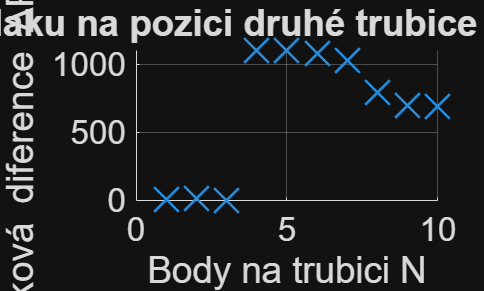

% Proměnné
bod_na_trubici = 1:10;
delta_P_trub = [12, 18, 4, 1110, 1105, 1084, 1032, 794, 702, 695];

fit_lin_dif = fit(bod_na_trubici(1:3).', delta_P_trub(1:3).', "poly1");
fit_coef_lin = coeffvalues(fit_lin_dif);

bod_lin = 0:3;
fit_lin_dif_fun = fit_coef_lin(1) * bod_lin + fit_coef_lin(2);

connection_x = [4,4];
connection_y = [0,1200];



figure(10)
    hold on
    plot(bod_na_trubici, delta_P_trub, 'x',LineWidth=1.5, MarkerSize=21);
    title("Závislost úbytku tlaku na pozici druhé trubice diferenčního tlakoměru")
    xlabel("Body na trubici N")
    ylabel("Tlaková diference \DeltaP [Pa]")
    fontsize(scale=1.95)

    grid on;

## Úkol 4. Porovnání s katalogovými údaji

% Proměnné

## Úkol 5. Nejistota citlivosti

% Proměnné
% Q = 100 nl*min^(-1)
f_100 = [74.91, 74.84, 75.05, 74.99, 74.88, 74.92, 74.76, 74.82, 74.88, 74.87];
f_150 = [110.0, 109.5, 109.7, 109.9, 109.8, 109.7, 109.7, 109.9, 110.0, 109.9];